clear
clear global logit_img
clc

addpath("../../algorithms/")

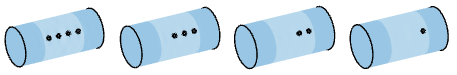

load("data\Phi.mat")
load("data\delta-B_circ2mmx4.mat")

Phi     = cat(3, real(Phi),     imag(Phi)    );
delta_B = cat(3, real(delta_B), imag(delta_B));

% for a = 0.1
% for b = 0.01:0.01:0.99
% 
% if a >= b, continue; end
clear global logit_img

for j = 1:length(shift)
    y = delta_B(:,j,:);

    beta = 1e+20 * ones(1,1,8);
    n = randn(size(y)) ./ sqrt(beta);
    y = y + n;

    local_img = binary_MF(Phi, y, 'a',a, 'b',b, 'beta',beta);
    % local_img = binary_CVX(Phi, y, 'beta',beta, 'c',1, 'MaxIterations',1, 'PrintDetails',true);

    [img, z_min] = mergeLocalImage(local_img, shift(j), voxels_corner);
end

% fprintf("a=%g, b=%g\n", a,b)
visualizeImage(img, z_min, voxels_corner, false)
drawnow


% end
% end

rho=11 (mm)


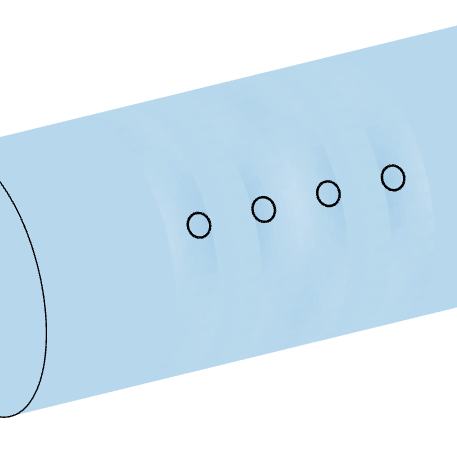

rho=11.5 (mm)


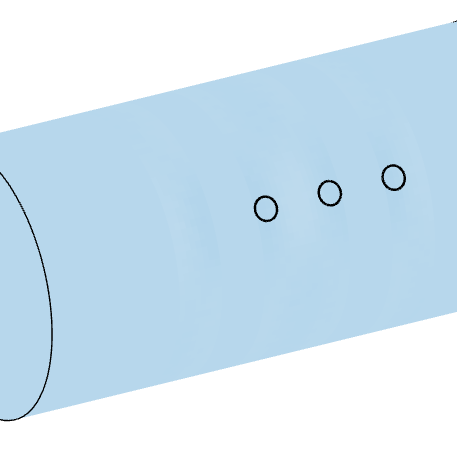

rho=12 (mm)


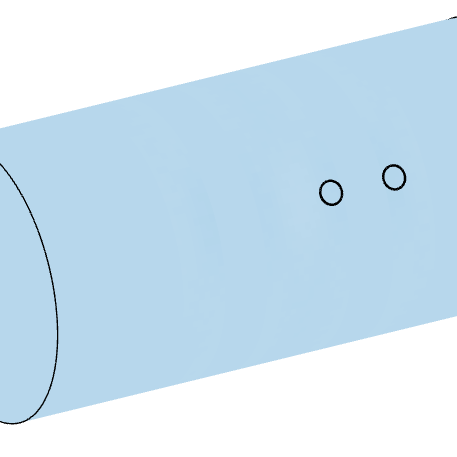

rho=12.5 (mm)


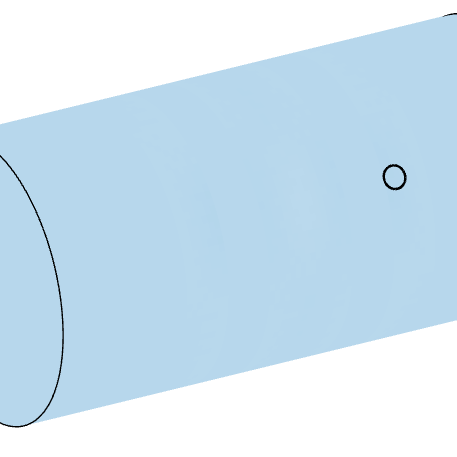

function [img, z_min] = mergeLocalImage(local_img, probe_z, voxels_corner)


rho = unique(voxels_corner(1,:)); num_rho = length(rho)-1;
phi = unique(voxels_corner(2,:)); num_phi = length(phi)-1;
z   = unique(voxels_corner(3,:)); dz = z(2) - z(1);

global logit_img z_min

logit_init = 0;
if isempty(logit_img)
    z_min = probe_z + z(1);
    logit_img = logit_init * ones(num_rho, num_phi, round((z(end)-z(1))/dz));
else
    z_max = z_min + size(logit_img,3) * dz;
    z_min_local = probe_z + z(1);
    z_max_local = probe_z + z(end);
    if z_min_local < z_min - 1e-8
        padder = logit_init * ones(num_rho, num_phi, round((z_min-z_min_local)/dz));
        logit_img = cat(3, padder, logit_img);
        z_min = z_min_local;
    end
    if z_max_local > z_max + 1e-8
        padder = logit_init * ones(num_rho, num_phi, round((z_max_local-z_max)/dz));
        logit_img = cat(3, logit_img, padder);
    end
end

local_img = reshape(local_img, length(rho)-1, length(phi)-1, length(z)-2);
logit_local_img = log(local_img ./ (1-local_img));
logit_local_img = clip(logit_local_img, -1e10, 1e10); % clamp the logit value to avoid irreversible states

z = [z(1:length(z)/2-1) z(length(z)/2+1:end-1)] + probe_z;
for k = 1:size(logit_local_img, 3)
    idx = round((z(k)-z_min)/dz+1);
    logit_img(:,:,idx) = logit_img(:,:,idx) + logit_local_img(:,:,k);
end

img = 1 ./ (1 + exp(-logit_img));

end

function visualizeImage(img, z_min, voxels_corner, seperate_figures)

if nargin < 4
    seperate_figures = false;
end

rho = unique(voxels_corner(1,:)); num_rho = length(rho)-1;
phi = unique(voxels_corner(2,:)); num_phi = length(phi)-1;
z   = unique(voxels_corner(3,:)); dz = z(2) - z(1);

if isempty(z_min)
    z_min = -size(img,3) * dz / 2;
end
z = z_min + (0:size(img,3)) * dz;
z_max = z(end);
[phi,z] = ndgrid(phi,z);

if ~seperate_figures
    figure
    tl = tiledlayout(1,num_rho, 'TileSpacing','tight', 'Padding','none');
    set(gcf, 'Position',[10 10 flip(tl.GridSize) .* [300 200]])
end

for i = 1:num_rho
    [x_,y_,z_] = evalCyl2simCart(rho(i+1), phi, z);
    c = squeeze(img(i,:,:));

    if ~seperate_figures
        nexttile
    else
        figure('Position',[100 100 600 600])
        fprintf('rho=%g (mm)\n',rho(i+1)*1e3)
    end

    surf(x_,y_,z_,c, 'LineStyle','none')
    clim([0 1])
    colormap sky
    axis equal off
    hold on
    
    theta = linspace(0,2*pi);
    plot3(z_min*ones(size(theta)), rho(i+1)*cos(theta), rho(i+1)*sin(theta), 'k')
    plot3(z_max*ones(size(theta)), rho(i+1)*cos(theta), rho(i+1)*sin(theta), 'k')

    defects_x = [-9 -3 3 9] * 1e-3;
    for defect_x = defects_x(i:end)
        x_ = 1e-3 * cos(theta) + defect_x;
        z_ = 1e-3 * sin(theta);
        y_ = -rho(i+1) * ones(size(theta));
        T = [cosd(30) sind(30); -sind(30) cosd(30)];
        coord = T * [y_; z_];
        y_ = coord(1,:); z_ = coord(2,:);
        plot3(x_, y_, z_, 'k', 'LineWidth',1.5)
    end

    view(-30,25)
    camtarget([0 0 0])
    camva(5.7)
end

end

function [x_,y_,z_] = evalCyl2simCart(rho,phi,z)
x_ = -z;
y_ = -rho .* cos(phi);
z_ =  rho .* sin(phi);
end